
%Link(theta,d,a,alpha,sigma,offset) 

l1 = 0.5;
l2 = 0.5;
% rvolute
L1 = Link([0 0  l1 0],'')

 
L1 = 
Revolute(std): theta=q, d=0, a=0.5, alpha=0, offset=0


L1.qlim = [-pi,pi];
L2 = Link ([0 0 0 pi/2, 0 pi/2],'standard')

 
L2 = 
Revolute(std): theta=q, d=0, a=0, alpha=1.5708, offset=1.5708


L2.qlim = [-pi/2 pi/2];
L3 = Link( [0 0 0 0 1 l2],'standard')

 
L3 = 
Prismatic(std): theta=0, d=q, a=0, alpha=0, offset=0.5


L3.qlim = [0 1];
figure
RP = L1+L2 +L3

 
RP = 
 
noname:: 3 axis, RRP, stdDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|        0.5|          0|          0|
|  2|         q2|          0|          0|     1.5708|     1.5708|
|  3|          0|         q3|          0|          0|        0.5|
+---+-----------+-----------+-----------+-----------+-----------+
 


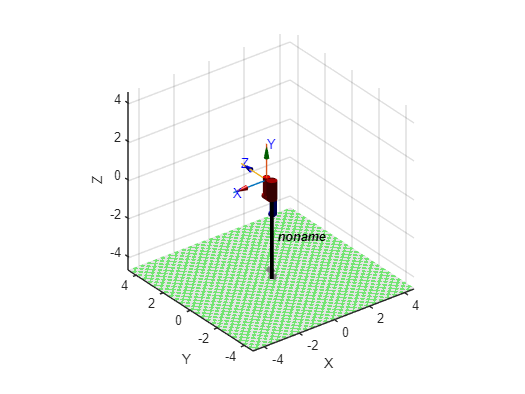

q = [45 45 0]*pi/180;
RP.teach(q,'jvec')


set(gcf,'Visible','on')

[~,A] = RP.fkine(q);
hold on

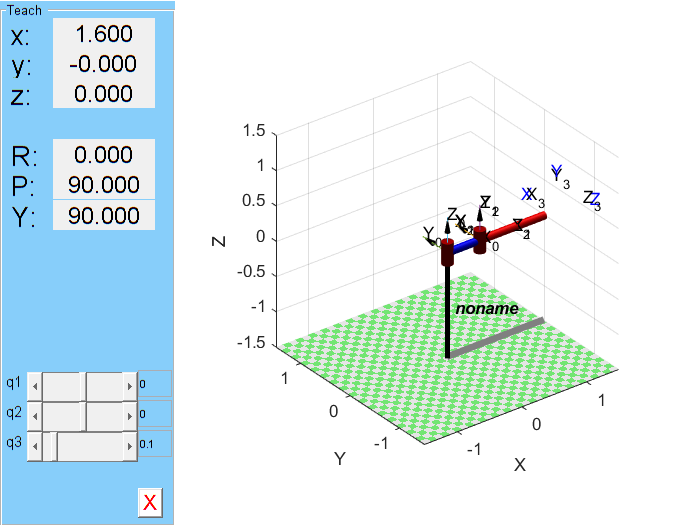

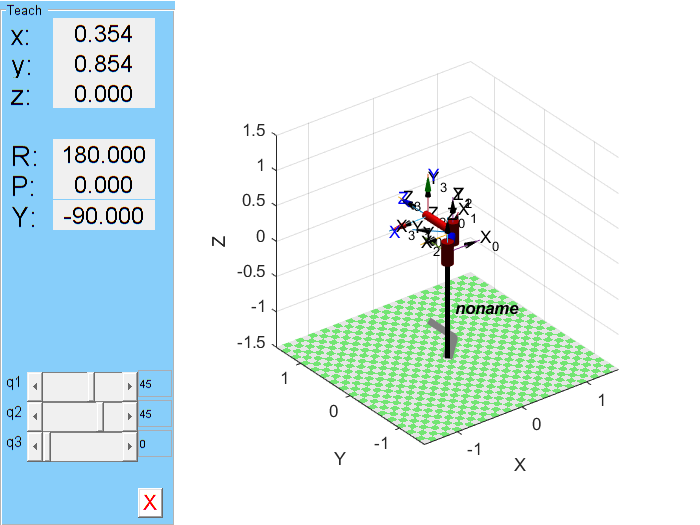


for i=0:3
    if i==0
        trplot(SE3([0 0 0]),'frame', num2str(i),'arrow','length',0.5,'color','k')
    else
        trplot(A(i), 'frame', num2str(i),'arrow','length',0.5,'color','k')
    end
end